%% DISLOCATION CREEP
% Gleason and Tullis, 1995
% Dislocation creep flow law script


% NOTES 
% CONTOUR PLOT, VARYING STRESS AND GRAIN SIZE 
% Grain size 1- 30 um
% Stress 10 - 100 MPa
% Format: 
% eps = [A'*(sig^n)*(fH20^r)]*exp(-Q/RT)

% Variables (Units)
% Eps = strain rate (1/s)
% A = Material constant (1/MPA^n * s^1)
% sig = flow stress (MPa)
% Q = creep activation energy (kJ/mol)
% R = gas constant
% T = absolute temperature (K) 
% fH2O = water fugacity (MPa)
% n =  stress exponent 
% r = fugacity exponent


% Input 

% IDEAL CONDITIONS (Hirth et al., 2001)
Apr_Hirth = 1e-11;
n_Hirth = 4;
Q_Hirth = 135; 
r_Hirth = 1;

% Input/ Non-Ideal Conditions 
A_DC = 1.5e-6 %1/MPa^n * S^1, CONSTANT

A_DC = 1.5000e-06

sig_DC = 30 %MPa, INPUT

sig_DC = 30

Q_DC = 118; %kJ/mol, INPUT (Koyama, Wallis)
R_DC = 8.314e-3; % CONSTANT
T_DC = 823.15 %K, INPUT

T_DC = 823.1500

n = 3; % (+/- 0.8)
fH2O = 65 % INPUT (Koyama, Wallis)

fH2O = 65

r = 1;
% First to calculate A' 
% A' = A/ fH20^r
Apr = A_DC / fH2O^r

Apr = 2.3077e-08


% Now the flow law 
eps_DC = (Apr*(sig_DC^n)*(fH2O^r))*exp(-Q_DC/(R_DC*T_DC))

eps_DC = 1.3160e-09

%% PRESSURE SOLUTION 
% Fisher, Hirth Flow Law
% First write a script to solve for solubility 
% Solubility (C (P,T))
% C(P,T) = Asol(P)exp[-Hsol(P/RT)]
% Hsol(P) = 28000 + 4500ln(P/200*10^6)
% Asol(P) = .0037exp[Hsol(P)/R*453K]

% Input Variables
P_PS = 500e6; % Pa (e6 converts to Pa)
T_PS = 623.15; % K
R_PS = 8.314; % (J/mol*K)

%Solve for Solubility C(P,T)
Hsol = 28000 + 4500*(log(P_PS/200e6)) % J/mol

Hsol = 3.2123e+04

Asol = .0037* exp(Hsol/(R_PS*453)) 

Asol = 18.7248

CPT = Asol* exp((-Hsol/(R_PS.*T_PS)))

CPT = 0.0380



% Flow Law
%   eps = (AC*sig/d^3)^(-Q/RT)
% eps = strain rate (s^-1)
A_PS = 1.5e-6; 
C = CPT

C = 0.0380

sig_PS = 70;
Q_PS = 50000; %(J/mol)
d_PS = 10

d_PS = 10


eps_PS = (A_PS*C*sig_PS/(d_PS^3))* exp(-Q_PS/(R_PS*T_PS))

eps_PS = 2.5674e-13


% Time range for plotting
T_Range = linspace(373,873,500);
Inv_T_Range = 1./T_Range;

% Lets make some contours by varying grain size (1-30um)
% all we have to do is change grain size to start  
% 1 micron 
dPS_1 = 1

dPS_1 = 1

eps_PS1 = (A_PS*C*sig_PS/(dPS_1^3))* exp(-Q_PS./(R_PS.*T_Range));

% 5 Micron 
dPS_5 = 5 

dPS_5 = 5

eps_PS5 = (A_PS*C*sig_PS/(dPS_5^3))* exp(-Q_PS./(R_PS.*T_Range));

% 15 Micron 
dPS_15 = 15

dPS_15 = 15

eps_PS15 = (A_PS*C*sig_PS/(dPS_15^3))* exp(-Q_PS./(R_PS.*T_Range));

% 23 Micron 
dPS_25 = 25

dPS_25 = 25

eps_PS25 = (A_PS*C*sig_PS/(dPS_25^3))* exp(-Q_PS./(R_PS.*T_Range));

% 30 Micron
dPS_30 = 30

dPS_30 = 30

eps_PS30 = (A_PS*C*sig_PS/(dPS_30^3))* exp(-Q_PS./(R_PS.*T_Range));


%% COMBINATION - GRAPH 
% Establish temperature range for samples 
% Plot will be log strain rate vs. 1/T

PS_T = (A_PS*C*sig_PS/(d_PS^3))* exp(-Q_PS./(R_PS.*T_Range));
DC_T = (Apr*(sig_DC^n)*(fH2O^r))*exp(-Q_DC./(R_DC.*T_Range));
figure()
plot(Inv_T_Range, PS_T, Color = 'blue', LineWidth = 1.5)
hold on;
plot(Inv_T_Range, DC_T, Color = 'red', LineWidth = 1.5)
% Now for our contours 
plot(Inv_T_Range, eps_PS1, Color = 'k', LineStyle= '--')
plot(Inv_T_Range, eps_PS5, Color = 'k', LineStyle= '--')
plot(Inv_T_Range, eps_PS15, Color = 'k', LineStyle= '--')
plot(Inv_T_Range, eps_PS25, Color = 'black', LineStyle= '--')
plot(Inv_T_Range, eps_PS30, Color = 'black', LineStyle= '--')

plot((1/T_PS), eps_PS, 'bo', 'MarkerSize',12, MarkerFaceColor='blue')
plot((1/T_DC), eps_DC, 'ro', 'MarkerSize',12, MarkerFaceColor='red')
% Axes, Formatting 
T_Range_C = linspace(100,700,500)

T_Range_C =   100.0000  101.2024  102.4048  103.6072  104.8096  106.0120  107.2144  108.4168  109.6192  110.8216  112.0240  113.2265  114.4289  115.6313  116.8337  118.0361  119.2385  120.4409  121.6433  122.8457  124.0481  125.2505  126.4529  127.6553  128.8577  130.0601  131.2625  132.4649  133.6673  134.8697  136.0721  137.2745  138.4770  139.6794  140.8818  142.0842  143.2866  144.4890  145.6914  146.8938  148.0962  149.2986  150.5010  151.7034  152.9058  154.1082  155.3106  156.5130  157.7154  158.9178


ylabel('log(strain rate)')
xlabel('1/T (K)')
set(gca,'Yscale','log');
ax1 = gca; 
ax1_pos = ax1.Position

ax1_pos =     0.1300    0.1100    0.7750    0.8150



ax2 = axes('Position', ax1_pos, 'XAxisLocation', 'top', 'YAxisLocation', 'right', 'Color', 'none')

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


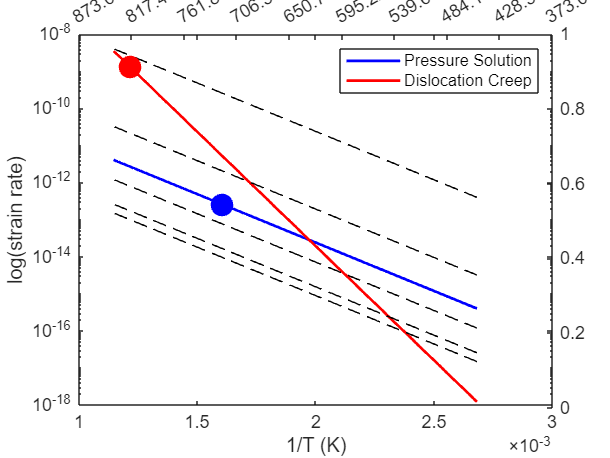

ax2.XLim = [min(T_Range), max(T_Range)];
ax2.XTick = linspace(min(T_Range), max(T_Range), 10);
set(ax2, 'XDir', 'reverse')
xlabel(ax2, 'Temperature(K)')
xtickformat(ax2, '%.2f')
legend(ax1, {'Pressure Solution', 'Dislocation Creep'})
print('HighResFigure', '-dpng', '-r300')
hold off; 